#                                                       Video Initialization and Parameter Setup

pixelScale=2;
v = VideoReader("sample.mp4");
fprintf("Duration : %.2f s \n",v.Duration);
fprintf("Height : %.2f  \n",v.Height);
fprintf("Width : %.2f  \n",v.Width);
fprintf("FrameRate : %.2f fps \n",v.FrameRate);
fprintf("Estimated Frames : %.2f  \n",v.Duration*v.FrameRate);

startFrame=1;
endFrame=v.Duration*v.FrameRate;
numFrames = endFrame - startFrame + 1;

## Array Preallocation

xdia = zeros(1, numFrames);
ydia = zeros(1, numFrames);
area_mm2 = zeros(1, numFrames);
x_centroid = zeros(1, numFrames);
y_centroid = zeros(1, numFrames);
y_top_raw= zeros(1, numFrames);
y_bottom_raw = zeros(1, numFrames);
area_rev_right=zeros(1, numFrames);
area_rev_left=zeros(1, numFrames);
dist_right_mm=zeros(1, numFrames);
dist_left_mm=zeros(1, numFrames);

## Read Video Frames

colorVidFrames = read(v, [startFrame endFrame]);

% Preallocate (use same class as rgb2gray output)
gFrames = zeros(v.Height, v.Width, numFrames, 'uint8');

for k = 1:numFrames
    J = rgb2gray(colorVidFrames(:,:,:,k));
    gFrames(:,:,k) = J;   % now gFrames(row, col, frame)
end

## Calibration: Calculate mm per pixel


% Extract Frame 1 from your grayscale video frames
frame1 = gFrames(:,:,1);

% 1. Isolate the bottom region to strictly target the base 
% (Cropping the bottom third avoids capturing the nozzle or droplet)
img_height = size(frame1, 1);
bottom_region = frame1(round(2*img_height/3):end, :);

% 2. Apply dynamic thresholding to isolate the dark substrate
thresh = graythresh(bottom_region);
base_mask = imbinarize(bottom_region, thresh);

% 3. Invert the mask (so the dark base becomes '1' or white)
base_mask = ~base_mask; 

% 4. Filter out any background noise, keeping only the largest object (the base)
base_mask = bwareafilt(base_mask, 1);

% 5. Extract the width of the isolated base using Regionprops
base_stats = regionprops(base_mask, 'BoundingBox');
base_width_pixels = base_stats(1).BoundingBox(3); % BoundingBox format: [x, y, width, height]

% 6. Calculate the conversion factor
substrate_width_mm = 15; % Known visible width of the surface
mmperpixel = substrate_width_mm / base_width_pixels;

% Display results
figure;
imshow(base_mask);
title('Isolated Base Mask for Calibration');
fprintf('Base Width in Pixels: %.1f\n', base_width_pixels);
fprintf('Calibration Factor = %.4f mm/pixel\n', mmperpixel);

## Initial Background Setup and Masking Test

% Extracted 30th frame to use as a static background reference
dlframe=gFrames(:,:,30);
dlframe(283:412,:)=255; 
Bframe2=imabsdiff(gFrames(:,:,1), dlframe); % Subtract the background from the 1st frame to isolate the moving droplet
Bframe2=Bframe2>50; % Apply a pixel intensity threshold to convert to a binary mask (black & white)
se=strel('disk',25);
Bframe2=imclose(Bframe2,se); % Perform morphological closing to smooth edges and connect broken regions
Bframe2 =imfill(Bframe2,'holes'); % Fill any empty black holes inside the white droplet mask
Bframe2=bwareafilt(Bframe2,1); %Filter out small noise artifacts, keeping only the 1 largest object (the droplet)
B1=bwboundaries(Bframe2); 
length(B1) % Display the number of objects found (should be 1)
% Show boundary across Frame1
figure
imshow(gFrames(:,:,1));
hold on

for k=1:length(B1)
    boundary = B1{k};
    plot(boundary(:,2),boundary(:,1),'r','LineWidth',2)
end
% Show area of detected droplet
stats3 = regionprops(Bframe2,'Area');
AR=stats3(1).Area*(mmperpixel^2);
fprintf('Area = %.2f mm^2\n', AR);
% Show the rectangular box detecting the droplet in Frame1
stats4 = regionprops(Bframe2, 'BoundingBox');

figure
imshow(gFrames(:,:,1));
hold on


box_dimensions1 = stats4(1).BoundingBox; 
rectangle('Position', box_dimensions1, 'EdgeColor', 'g', 'LineWidth', 2);

## Main Loop: Droplet Tracking and Feature Extraction

Bframe=gFrames;
% Used The above masking technique to apply masking to all frames
for i=1:numFrames
    Bframe(:,:,i)=imabsdiff(Bframe(:,:,i), dlframe);
    Bframe1=Bframe(:,:,i);
    Bframe1=Bframe1>50;
    se=strel('disk',25);
    Bframe1=imclose(Bframe1,se);
    Bframe1 =imfill(Bframe1,'holes');
    Bframe1=bwareafilt(Bframe1,1);
    B=bwboundaries(Bframe1);
    stats1 = regionprops(Bframe1, 'BoundingBox','Centroid'); % Extract spatial properties (Bounding Box and Center of Mass)
    box_dimensions = stats1(1).BoundingBox; % Format: [x_corner, y_corner, width, height]
    stats_area = regionprops(Bframe1, 'Area');
    area_mm2(i) = stats_area(1).Area * (mmperpixel^2);
    % Calculate horizontal and vertical diameters using Bounding Box width/height
    xdia(i)=box_dimensions(3)*mmperpixel; % Width
    ydia(i)=box_dimensions(4)*mmperpixel; % Height
    % Calculate the physical (X, Y) coordinates of the droplet's center of mass
    x_centroid(i) = stats1(1).Centroid(1) * mmperpixel;
    y_centroid(i) = stats1(1).Centroid(2) * mmperpixel;
    % Calculate the raw top-down physical locations of the droplet's upper and lower edges
    y_top_raw(i) = box_dimensions(2)* mmperpixel; 
    y_bottom_raw(i) =( box_dimensions(2) + box_dimensions(4))* mmperpixel;
    % Calculate horizontal and vertical axis using Bounding Box width/height
    x_axis_of_sym = (box_dimensions(1) + box_dimensions(3)/2) * mmperpixel;
    y_axis_of_sym = (box_dimensions(2) + box_dimensions(4)/2) * mmperpixel;
    %1. Find the central vertical axis of the whole droplet
    stats_full = regionprops(Bframe1, 'Centroid', 'BoundingBox');
    center_x_px = stats_full(1).Centroid(1);

    right_mask = Bframe1;
    right_mask(:, 1:floor(center_x_px)) = 0; % Erase left side
    right_mask = bwareafilt(right_mask, 1);  % Remove cut-line splinters

    stats_right = regionprops(right_mask, 'Area', 'Centroid');
    area_rev_right(i) = stats_right(1).Area * (mmperpixel^2);
    dist_right_mm(i) = abs(stats_right(1).Centroid(1) - center_x_px) * mmperpixel;

    % 3. Left Half Mask Processing
    left_mask = Bframe1;
    left_mask(:, ceil(center_x_px):end) = 0; % Erase right side
    left_mask = bwareafilt(left_mask, 1);    % Remove cut-line splinters

    stats_left = regionprops(left_mask, 'Area', 'Centroid');
    area_rev_left(i) = stats_left(1).Area * (mmperpixel^2);
    dist_left_mm(i) = abs(stats_left(1).Centroid(1) - center_x_px) * mmperpixel;
end

## Plotting: Droplet Dimensions Over Time

fps_original = v.FrameRate; 
time_array = (1:numFrames) / fps_original; % Created Time array
disp(mean(xdia));

    2.2490



disp(mean(ydia));

    2.0648



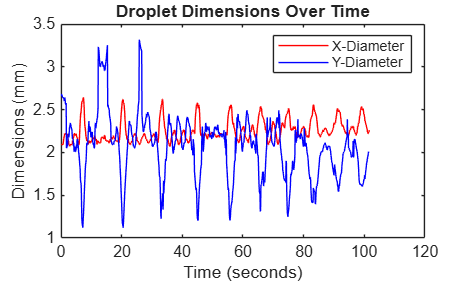

figure;
plot(time_array, xdia, 'r', 'DisplayName', 'X-Diameter');
hold on;
plot(time_array, ydia, 'b', 'DisplayName', 'Y-Diameter');

% Update the labels
xlabel('Time (seconds)');
ylabel('Dimensions (mm)'); 
title('Droplet Dimensions Over Time');
legend('show');

## Plotting: Droplet Volume (Pappus-Guldinus)

Calculate the radius of a perfect circle with that same area

% Calculate volume using the stabilized inputs
% Calculate the independent Pappus-Guldinus volumes for each half
vol_right = 2 * pi * dist_right_mm .* area_rev_right;
vol_left  = 2 * pi * dist_left_mm.* area_rev_left;

% Average the two sides to mathematically cancel lateral wobbling
volume_mm3_area = (vol_right + vol_left) / 2;
% --- Droplet Volume Output  ---
fprintf('\n--- Droplet Volume Report  ---\n');


--- Droplet Volume Report  ---


fprintf('Initial calculated volume: %.3f uL\n', volume_mm3_area(1));

Initial calculated volume: 5.266 uL


fprintf('Maximum calculated volume: %.3f uL\n', max(volume_mm3_area));

Maximum calculated volume: 6.095 uL


fprintf('Minimum calculated volume: %.3f uL\n', min(volume_mm3_area));

Minimum calculated volume: 4.636 uL


fprintf('Mean calculated volume: %.3f uL\n', mean(volume_mm3_area));

Mean calculated volume: 5.394 uL


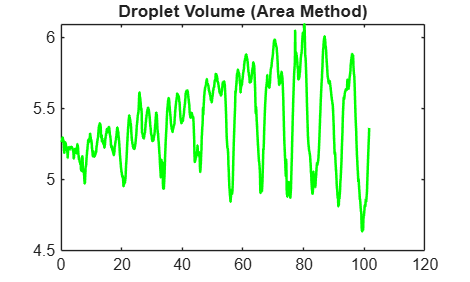


% Plot the calculated volume
figure;
plot(time_array, volume_mm3_area, 'g', 'LineWidth', 1.5);
title('Droplet Volume (Area Method)');

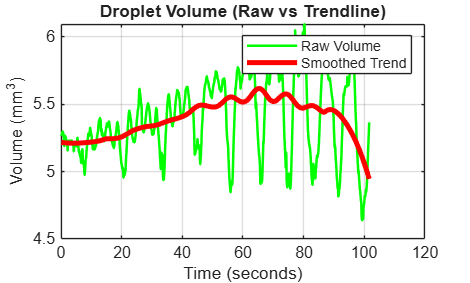


% Create the ultra-smooth trendline
volume_trend = smoothdata(volume_mm3_area, 'loess', 300); 

figure;
% Plot the raw oscillating data first (Green)
plot(time_array, volume_mm3_area, 'g', 'LineWidth', 1.5, 'DisplayName', 'Raw Volume');

% Lock the graph so the next line draws on top of it instead of replacing it
hold on; 

% Plot the smoothed trendline on top (Red and Thicker)
plot(time_array, volume_trend, 'r', 'LineWidth', 3, 'DisplayName', 'Smoothed Trend');

% Add labels
xlabel('Time (seconds)');
ylabel('Volume (mm^3)');
title('Droplet Volume (Raw vs Trendline)');
legend('show');
grid on;

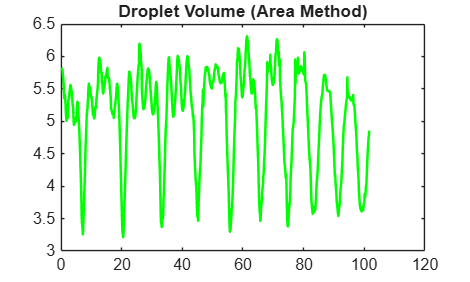

%% Plotting: Droplet Volume (Area Method)
% Calculate the radius of a perfect circle with that same area

eq_radius = sqrt(area_mm2 / pi);

% Calculate the volume of a perfect sphere using that radius
volume_mm3_area1 = (4/3) * pi * (eq_radius.^3);

% Plot the calculated volume
figure;
plot(time_array, volume_mm3_area1, 'g', 'LineWidth', 1.5);
title('Droplet Volume (Area Method)');


% Create the ultra-smooth trendline
volume_trend = smoothdata(volume_mm3_area1, 'loess', 300); 

figure;
% Plot the raw oscillating data first (Green)
plot(time_array, volume_mm3_area1, 'g', 'LineWidth', 1.5, 'DisplayName', 'Raw Volume');

% Lock the graph so the next line draws on top of it instead of replacing it
hold on; 

% Plot the smoothed trendline on top (Red and Thicker)
plot(time_array, volume_trend, 'r', 'LineWidth', 3, 'DisplayName', 'Smoothed Trend');
% --- Droplet Volume Output  ---
fprintf('\n--- Droplet Volume Report  ---\n');


--- Droplet Volume Report  ---


fprintf('Initial calculated volume: %.3f uL\n', volume_mm3_area1(1));

Initial calculated volume: 5.824 uL


fprintf('Maximum calculated volume: %.3f uL\n', max(volume_mm3_area1));

Maximum calculated volume: 6.314 uL


fprintf('Minimum calculated volume: %.3f uL\n', min(volume_mm3_area1));

Minimum calculated volume: 3.209 uL


fprintf('Mean calculated volume: %.3f uL\n', mean(volume_mm3_area1));

Mean calculated volume: 5.080 uL


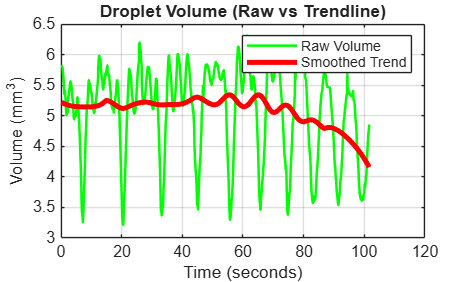

% Add labels
xlabel('Time (seconds)');
ylabel('Volume (mm^3)');
title('Droplet Volume (Raw vs Trendline)');
legend('show');
grid on;

## Plotting: Figure 6 (Droplet Height vs. Time)

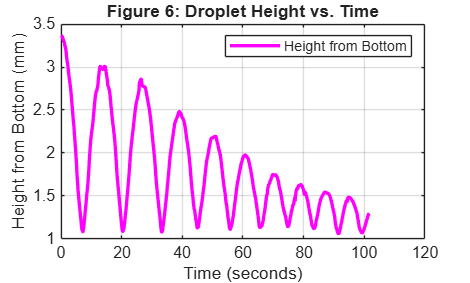

% Height of the Frame in mm
y_height=482*mmperpixel; 
y_centroidplot =y_height- y_centroid;

figure;
plot(time_array, y_centroidplot, 'm', 'LineWidth', 2, 'DisplayName', 'Height from Bottom');
xlabel('Time (seconds)');
ylabel('Height from Bottom (mm)'); 
title('Figure 6: Droplet Height vs. Time');
legend('show');
grid on;

## Plotting: Figure 7 (Raw Top and Bottom Boundaries)

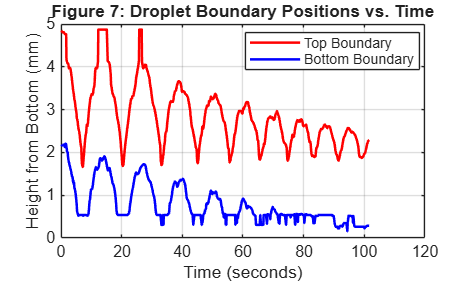

y_top=y_height-y_top_raw;
y_bottom=y_height-y_bottom_raw;

figure;
plot(time_array, y_top, 'r', 'LineWidth', 1.5, 'DisplayName', 'Top Boundary');
hold on;
plot(time_array, y_bottom, 'b', 'LineWidth', 1.5, 'DisplayName', 'Bottom Boundary');
xlabel('Time (seconds)');
ylabel('Height from Bottom (mm)'); 
title('Figure 7: Droplet Boundary Positions vs. Time');
legend('show', 'Location', 'best');
grid on;

## Bounce Detection and Filtering

Smooth out the raw pixel flicker with a small 15-frame window

y_top = smoothdata(y_top, 'gaussian', 15);
y_bottom = smoothdata(y_bottom, 'gaussian', 15);

% Find distinct peaks in the top boundary. 
% MinPeakProminence of 1.0 ensures we only count major physical rebounds, ignoring optical noise.
[bounce_heights, bounce_indices] = findpeaks(y_top, 'MinPeakProminence', 0.5);
bounce_times = time_array(bounce_indices);
total_bounces = length(bounce_heights);

% Print the official total to the Command Window
fprintf('\n--- Experiment Results ---\n');


--- Experiment Results ---


fprintf('Total number of bounces observed: %d\n\n', total_bounces);

Total number of bounces observed: 9



## Final Plotting: Figure 7 (Filtered Boundaries with Bounces)

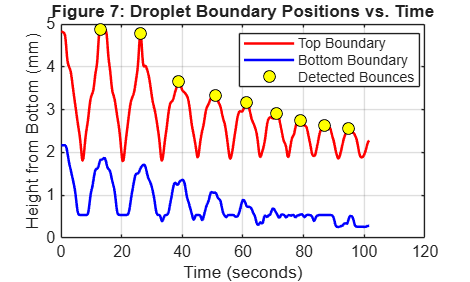

figure;
plot(time_array, y_top, 'r', 'LineWidth', 1.5, 'DisplayName', 'Top Boundary');
hold on;
plot(time_array, y_bottom, 'b', 'LineWidth', 1.5, 'DisplayName', 'Bottom Boundary');

% Mark the bounces on the graph (Yellow circles with black outlines)
plot(bounce_times, bounce_heights, 'ko', 'MarkerFaceColor', 'y', 'MarkerSize', 7, 'DisplayName', 'Detected Bounces');

xlabel('Time (seconds)');
ylabel('Height from Bottom (mm)'); 
title('Figure 7: Droplet Boundary Positions vs. Time');
legend('show', 'Location', 'best');
grid on;

%% Key Results (recalculated with new calibration)

first_peak = bounce_indices(1);       % frame of first rebound peak
last_peak  = bounce_indices(end);     % frame of last rebound peak

% 1. Energy loss on first impact (using centroid = centre of mass)
yc = smoothdata(y_centroidplot, 'gaussian', 15);   % smooth centroid height
h_rest = yc(end);                                  % resting centroid level
[~, impact_idx] = min(yc(1:first_peak+50));        % lowest point = first impact
h0 = max(yc(1:impact_idx)) - h_rest;               % highest point before impact
[pk, ~] = findpeaks(yc(impact_idx:end), 'MinPeakProminence', 0.2);
h1 = pk(1) - h_rest;                               % first rebound peak after impact
E_loss = (1 - h1/h0) * 100;

% 2. Deformation limits during first collision (start to first rebound peak)
x_max = max(xdia(1:first_peak));
y_min = min(ydia(1:first_peak));

% 3. Resting centroid height above the impact surface
surface_level = y_bottom(end);        % bottom edge at rest = substrate
h_centroid_rest = y_centroidplot(end) - surface_level;

% 4. Volume during bouncing vs settled phase (Pappus-Guldinus)
V_active  = mean(volume_mm3_area(1:last_peak));
V_settled = mean(volume_mm3_area(last_peak:end));

fprintf('\n--- Key Results ---\n');


--- Key Results ---


fprintf('Initial drop height      = %.3f mm\n', h0);

Initial drop height      = 2.075 mm


fprintf('First rebound height     = %.3f mm\n', h1);

First rebound height     = 1.715 mm


fprintf('Energy lost on 1st impact = %.2f %%\n', E_loss);

Energy lost on 1st impact = 17.37 %


fprintf('Max X-diameter (impact)  = %.3f mm\n', x_max);

Max X-diameter (impact)  = 2.641 mm


fprintf('Min Y-diameter (impact)  = %.3f mm\n', y_min);

Min Y-diameter (impact)  = 1.120 mm


fprintf('Resting centroid height  = %.3f mm above surface\n', h_centroid_rest);

Resting centroid height  = 1.012 mm above surface


fprintf('Mean volume (bouncing)   = %.3f mm^3\n', V_active);

Mean volume (bouncing)   = 5.407 mm^3


fprintf('Mean volume (settled)    = %.3f mm^3\n', V_settled);

Mean volume (settled)    = 5.220 mm^3
